依赖[统一实验分析作图v19.1.0](https://github.com/ShanghaitechGuanjisongLab/Unified-Experimental-Analysis-and-Figuring/releases/)

声转光一个典型细胞的示例

QueryTable=UniExp.ReadQueryTable(TransferLearning.ProjectPath('查询表.xlsx'),'Fig1F');
CellNts=TransferLearning.FullCalcium.QueryNTS(QueryTable,UniExp.Flags.dFdF0,1:24);

CellUID=structfun(@(S)S.CellUID,CellNts,UniformOutput=false);
CellUID=MATLAB.Ops.IntersectN(1,CellUID.Naive_cue,CellUID.Naive,CellUID.Learned,CellUID.Transfer);
GroupNames=["Naive_cue","Naive","Learned","Transfer"];
for G=1:4
	NTS=CellNts.(GroupNames(G));
	[~,Index]=ismember(CellUID,NTS.CellUID);
	NTS=NTS(Index,:);
	[NTS.PeakValue,NTS.PeakTime]=max(NTS.TrialSignal(:,25:32),[],2);
	CellNts.(GroupNames(G))=NTS;
end
Logical=CellNts.Learned.PeakTime==CellNts.Transfer.PeakTime;
[Delta,Index]=max(min(CellNts.Learned.PeakValue(Logical),CellNts.Transfer.PeakValue(Logical)));
Index=find(Logical,Index);
Index=Index(end);
CellUID=CellUID(Index);

PlotData=zeros(40,4);
for G=1:4
	PlotData(:,G)=CellNts.(GroupNames(G)).TrialSignal(Index,:);
end
PlotData(:,2)=PlotData(:,2)+max(PlotData(:,3))-min(PlotData(:,2));
PlotData(:,1)=PlotData(:,1)+max(PlotData(:,2))-min(PlotData(:,1));

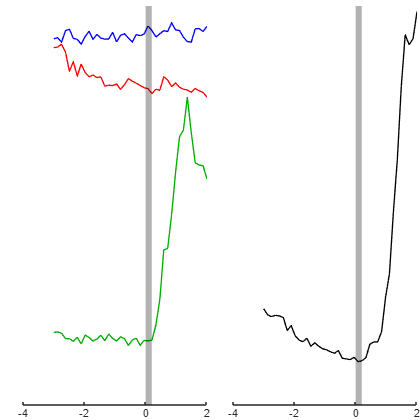

Fig=figure;
Axes=gobjects(1,2);
Xs=linspace(-3,2,40);
colororder([0,0,1;1,0,0;0,0.681,0]);
Layout=tiledlayout(1,2,TileSpacing='tight',Padding='tight');
Axes(1)=nexttile;
line(Xs,PlotData(:,1:3),LineWidth=1);
Axes(2)=nexttile;
line(Xs,PlotData(:,4),Color=[0,0,0],LineWidth=1);
MATLAB.Graphics.UnifyAxesLims(Axes,@ylim);
MATLAB.Graphics.FigureAspectRatio(1,1,MATLAB.Flags.Narrow);
for A=Axes
	A.YAxis.Visible='off';
	patch(A,[0,0.2,0.2,0],repelem(ylim,1,2),[0,0,0],FaceAlpha=0.3,LineStyle='none');
end
print(Fig,TransferLearning.ProjectPath('Fig1F.svg'),'-dsvg');